# Archivo Principal. Modelo MAS y mecanismo para gestión de demanda.


% Test for mechanism with social incentives (opinion dynamics), with Bullo stubbornnes model. 
% Replicator dynamics used for resource allocation optimization.

clear all
clc
close all

global G beta_ef N T_ hybrid b op devices

devices = xls2struct('devices.xlsx'); %cargar los aparatos que tienen las casas de cada usuario.
%load('Prefs.mat');
%number of populations (consumers, households)
P = 50;
% number of agents per population (devices)
N = length(devices.id);

%step_1_graph(P) % graph network generation, for the user's opinions interaction
%step_2_opdyn % opinion dynamics

## Users preferences

T_ = 14;%168/4;%10080/5; %weekly period with hourly resolution.
Tperf = 10080; % Perfiles generados con resolucion de 1 min.


 PrefsOrig = zeros(N,Tperf,P);%randi([0 1], N,T_,P);
 Perfiles = Perfcas2(P,1);

No genera gráfica
Fin perfil Nevera 3
No genera gráfica
Fin perfil Luminaria2OC
No genera gráfica
Fin perfil Luminaria2OC
No genera gráfica
Fin perfil Luminaria
No genera gráfica
Fin perfil Luminaria
No genera gráfica
Fin perfil Luminaria
No genera gráfica
Fin perfil Luminaria
No genera gráfica
Fin perfil Ducha
No genera gráfica
Fin perfil Lavadora
No genera gráfica
Fin perfil Lavadora
No genera gráfica
Fin perfil Lavadora
No genera gráfica
Fin perfil Lavadora
No genera gráfica
Fin perfil Plancha
No genera gráfica
Fin perfil Lavadora
No genera gráfica
Fin perfil Lavadora
No genera gráfica
Fin perfil Cargador Pc Portatil
No genera gráfica
Fin perfil Cargador Celular
No genera gráfica
Fin perfil Cargador Celular
No genera gráfica
Fin perfil Cargador Celular
No genera gráfica
Fin perfil Cargador Celular
No genera gráfica
Fin perfil Cargador Celular
No genera gráfica
Fin perfil Cargador Celular
No genera gráfica
Fin perfil Horno Microondas
No genera gráfica
Fin perfil Licuadora
No genera g

 
 
 kWhOrig = sum(Perfiles.Total)/60;

for i=1:length(devices.id)
    %update default power definition for each device with data in the
    %profiles
    devices.power(i) = ceil(max(max(Perfiles.(devices.id{i}))));
    
    %copy Perfiles to variable Prefs, changing organisation
    
    for u = 1:P
        PrefsOrig(i,:,u) = Perfiles.(devices.id{i})(:,u);
    end
    
end

%Undersampling of the profiles, to match game runtime periods.
factor = Tperf/T_;

% number of pure strategies per population
n = min(factor,100); %calculated for getting a porportion of the period in 1 min steps. If more than 100 strategies are required, they are set to 100.

Prefs = pUndersample(PrefsOrig, factor,n); %real valued vector, from the interval [0,1]

%save('Prefs','Prefs','PrefsOrig','Perfiles','devices')

%length(nonzeros(PrefsOrig(1,:,1)))
%length(nonzeros(Prefs(1,:,1)))*factor

% PowOpt = zeros(N,T_); No se pr que esta forma de sacar la potencia total no funciona.
% for u = 1:P
%     PowOpt = PowOpt + sum(devices.power.*squeeze(Prefs(:,:,u)));
% end
% PowOptTotal = sum(PowOpt)/1000';

PowOptTotal = zeros(1,T_);

for t = 1:T_
PowOptTotal(t) = sum(sum(devices.power.*squeeze(Prefs(:,t,:))))/1000;
end


## Periods for applying incentives

Iperiods = PowOptTotal > 21; %>10mean(PowOptTotal);%zeros(size(PowOptTotal));

Iper(Iperiods);

## Stuff


% parametros de la func. de costo agregado
%beta_ef = 450; 
b = 0;

## discrete

Running the logit_choice revision protocol, period T=1
  Columns 1 through 5

         0         0         0         0         0
   -0.0000         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0   -0.0000    0.0000   -0.0000    0.0000
   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100
         0         0         0         0         0
         0         0         0         0         0
   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100
         0         0         0   -0.0100         0

  Columns 6 through 10

         0         0         0         0         0
         0   -0.0100         0         0         0
         0         0         0

Running the logit_choice revision protocol, period T=2
  Columns 1 through 5

         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
   -0.0000         0         0   -0.0000   -0.0000
         0         0         0         0   -0.0000
   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100
         0         0         0         0         0
         0         0         0         0         0
         0    0.0000         0         0         0
         0         0         0         0         0
         0         0         0   -0.0000         0
         0         0         0         0         0
         0         0         0         0         0
   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100
         0         0         0         0         0

  Columns 6 through 10

         0    0.0100         0         0         0
         0         0         0         0         0
         0         0   -0.0100

Running the logit_choice revision protocol, period T=3
  Columns 1 through 5

         0         0         0   -0.0100         0
         0   -0.0000         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100
         0         0         0         0         0
         0         0         0         0         0
         0   -0.0000         0         0         0
         0         0         0         0         0
   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100
         0         0   -0.0100   -0.0100         0
         0         0         0         0         0
   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100
         0         0         0         0         0

  Columns 6 through 10

         0         0         0         0   -0.0100
         0         0         0         0         0
         0         0         0

Running the logit_choice revision protocol, period T=4
  Columns 1 through 5

         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
   -0.0100         0         0   -0.0000         0
         0         0         0         0         0
   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100
         0         0         0         0         0
         0         0         0         0         0
         0         0    0.0000         0   -0.0000
   -0.0000         0   -0.0000         0   -0.0100
         0   -0.0000         0         0         0
         0         0         0         0         0
         0         0         0         0         0
   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100
         0   -0.0000         0         0         0

  Columns 6 through 10

         0         0         0         0         0
         0         0         0         0         0
         0         0         0

Running the logit_choice revision protocol, period T=5
  Columns 1 through 5

         0         0         0         0         0
         0         0         0         0         0
         0         0   -0.0100         0         0
         0         0   -0.0000         0         0
         0         0         0   -0.0100         0
   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100
   -0.0100         0         0         0         0
         0         0         0         0         0
         0         0         0         0   -0.0000
         0         0         0         0         0
   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100
         0         0   -0.0100         0   -0.0100
         0         0         0         0         0
   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100
         0         0         0         0   -0.0000

  Columns 6 through 10

         0         0         0         0         0
         0         0         0         0         0
         0         0         0

Running the logit_choice revision protocol, period T=6
  Columns 1 through 5

         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0   -0.0000         0
         0         0         0         0         0
   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100
         0         0         0         0         0
         0         0         0         0         0
         0   -0.0000         0         0         0
         0         0         0         0         0
         0         0         0   -0.0000         0
         0         0         0         0         0
         0         0         0         0         0
   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100
    0.0000   -0.0000         0         0         0

  Columns 6 through 10

         0         0         0         0         0
   -0.0000         0   -0.0000         0         0
         0         0         0

Running the logit_choice revision protocol, period T=7
  Columns 1 through 5

         0         0    0.0100         0         0
   -0.0000         0         0         0         0
         0         0         0         0         0
    0.0000         0   -0.0000         0         0
         0         0         0         0         0
   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0   -0.0000
         0         0   -0.0000         0         0
   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100
         0         0         0         0         0
         0         0         0         0         0
   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100
    0.0000   -0.0000         0         0         0

  Columns 6 through 10

         0         0         0         0         0
         0         0         0         0   -0.0000
         0         0         0

Running the logit_choice revision protocol, period T=8
  Columns 1 through 5

         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0   -0.0000    0.0000         0   -0.0000
   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100
         0         0         0         0         0
         0         0         0   -0.0100         0
         0         0         0   -0.0100         0
         0         0         0         0         0
   -0.0000         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100
         0   -0.0000         0         0         0

  Columns 6 through 10

         0         0         0         0         0
         0         0         0         0         0
         0         0         0

Running the logit_choice revision protocol, period T=9
  Columns 1 through 5

         0         0         0         0         0
   -0.0000         0         0         0         0
         0         0   -0.0100         0         0
   -0.0000         0   -0.0100         0         0
         0         0         0         0   -0.0000
   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100
         0         0         0         0         0
         0         0         0         0         0
         0   -0.0000    0.0000    0.0100         0
         0   -0.0000         0         0         0
   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100
         0         0         0         0   -0.0100
         0         0         0         0         0
   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100
         0         0         0   -0.0000   -0.0000

  Columns 6 through 10

         0         0         0         0         0
         0         0         0   -0.0000         0
         0         0         0

Running the logit_choice revision protocol, period T=10
  Columns 1 through 5

         0         0         0         0         0
         0         0         0         0   -0.0000
         0         0         0         0         0
         0         0         0         0         0
         0   -0.0100   -0.0000   -0.0000         0
   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100
         0         0   -0.0100         0   -0.0100
         0         0         0         0   -0.0100
         0         0         0         0         0
         0         0         0         0   -0.0000
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100
         0         0         0         0         0

  Columns 6 through 10

         0         0         0         0         0
         0         0         0         0         0
         0         0   -0.010

Running the logit_choice revision protocol, period T=11
  Columns 1 through 5

         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0    0.0000         0         0   -0.0100
         0         0         0         0   -0.0000
   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100
         0         0         0         0         0
         0         0         0   -0.0100         0
   -0.0000   -0.0000         0    0.0000         0
         0   -0.0000         0         0    0.0000
   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100
         0         0         0         0   -0.0100
         0         0         0   -0.0100         0
   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100
         0         0         0         0   -0.0100

  Columns 6 through 10

         0         0         0         0         0
   -0.0000         0         0         0         0
         0         0         

Running the logit_choice revision protocol, period T=12
  Columns 1 through 5

         0         0    0.0100         0         0
         0         0         0   -0.0000         0
   -0.0100         0         0   -0.0100         0
    0.0000         0         0   -0.0000         0
         0         0         0   -0.0000   -0.0100
   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100
         0         0         0         0         0
         0         0         0         0         0
         0         0         0   -0.0000         0
         0         0         0         0   -0.0000
         0         0         0         0         0
   -0.0100         0         0         0         0
         0         0         0         0         0
   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100
         0         0         0         0   -0.0000

  Columns 6 through 10

         0         0         0         0         0
         0         0         0   -0.0000         0
         0         0         

Running the logit_choice revision protocol, period T=13
  Columns 1 through 5

         0         0         0         0         0
         0         0   -0.0000         0         0
         0   -0.0100   -0.0100         0         0
         0         0         0         0    0.0000
         0         0         0   -0.0100         0
   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0    0.0000         0         0         0
   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100
         0         0         0         0         0
         0         0         0         0         0
   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100
    0.0000         0         0         0         0

  Columns 6 through 10

         0         0         0         0         0
   -0.0000   -0.0000         0         0         0
         0         0         

Running the logit_choice revision protocol, period T=14
  Columns 1 through 5

         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
   -0.0000         0         0         0         0
         0   -0.0000         0    0.0000         0
   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0   -0.0000         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100
   -0.0100         0         0         0         0

  Columns 6 through 10

         0         0         0         0         0
         0   -0.0000         0   -0.0000         0
         0         0   -0.010

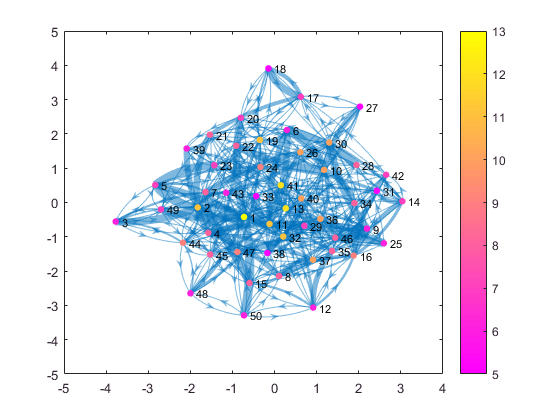

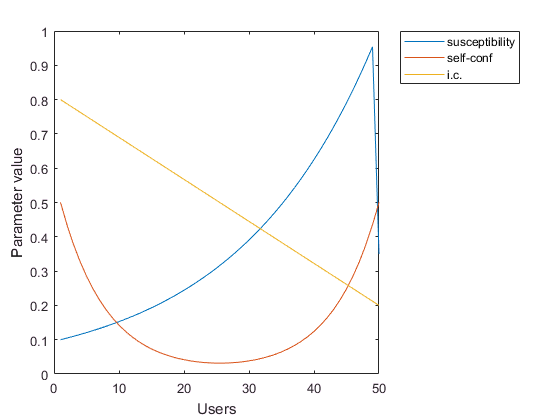

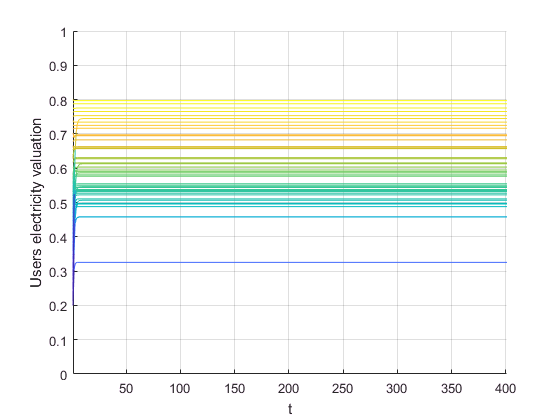

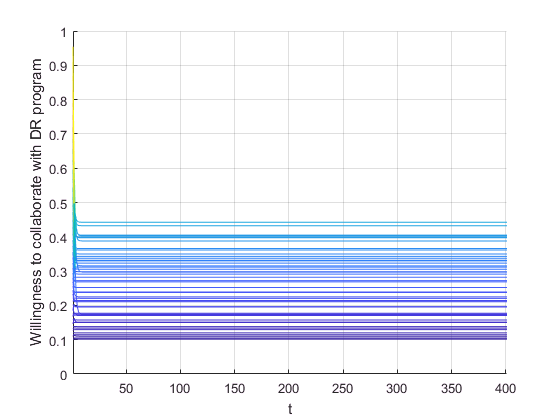

% mass of the population
%m = 1;

% initial condition
%x0 = 0; %[0.2 0.7 0.1]; 

% simulation parameters
iterations = 400;

% structure with the parameters of the game
G = struct('P', P, 'N', N, 'n', n, 'pop_wise', 0, 'f', @fitness_user_finite, 'time', iterations, 'eta', 0.02, 'revision_protocol', @logit_choice);

G.R = 1;% There are as many revisions per iteration as agents are in a population.


% verify data of the game
G = definition(G);

G.T_ = T_; %assign run periods to the ciclic game.
G.Prefs = Prefs; %users' preferences for each period.

Qp = zeros(T_,G.P);
Incentives = zeros(G.T_,G.time,G.N,G.P);

tdyn = tic;
for run = 1:G.T_
G.period = run; %present period
G.run_finite();
Incentives(run,:,:,:) = reshape(G.Inc,[G.time,G.N,G.P]);
Qperiod = reshape(G.Q(end,:),G.N,G.P);
Qp(run,:) = sum(Qperiod)/1000;
end


totaldyn = toc(tdyn);
disp(['Total elapsed time running pop dynamics: ',num2str(totaldyn),' s'])

Total elapsed time running pop dynamics: 117.636 s


disp(' ')

%G.graph()
%G.graph_evolution()
%G.graph_fitness()

## continues standard

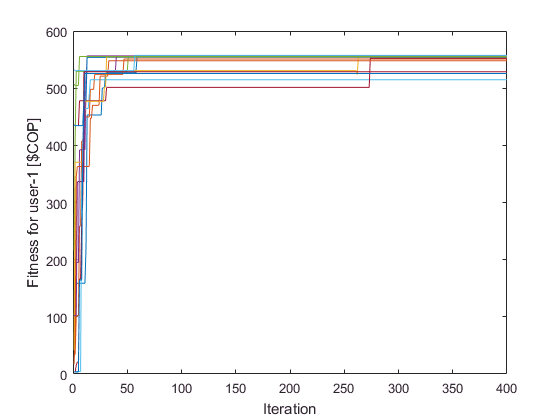

Q_e = reshape(G.Q(end,:), [G.N,G.P]);
Q_s = reshape(G.Q(1,:), [G.N,G.P]);

user = 1;
FitEvo = zeros(G.time,G.N);
for t = 1:G.time
FitEvo(t,1:G.N) = G.F(t,user*(1:G.N));
end

figure(10)
tfit = 1:G.time;
plot(tfit,FitEvo)
xlabel('Iteration');
yinfo = strcat('Fitness for user','-',num2str(user),' [$COP]');
ylabel(yinfo)



% extract matrix of strategies. 
%MC. A strategy to make a consumption in a specific time t.
%x_n = vec2mat(G.X(end, :), n);

## Calculos de potencia por periodo

timem = 1:T_;
Qpt = sum(Qp,2);

disp('Coincide la potencia del caso natural(prefs) con la consumida:')

Coincide la potencia del caso natural(prefs) con la consumida:


size(nonzeros(eq(PowOptTotal'*1000, round(Qpt*1000))))

ans =      0     1


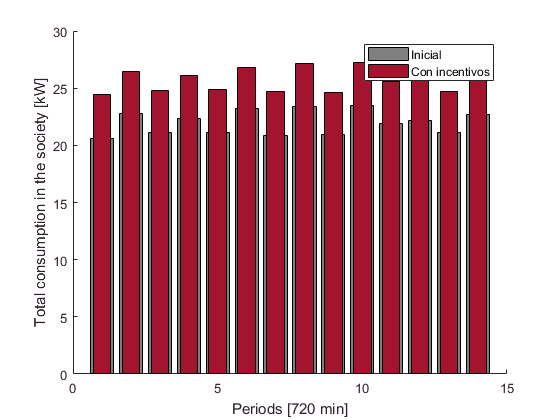



labelperiods  = periodClass(T_);

figure(1);
hold on;
bar(timem,PowOptTotal,0.8,'FaceColor',[.5 .5 .5]);
bar(timem,Qpt,0.6,'FaceColor',[.64 .08 .18]);

legend('Inicial','Con incentivos')
xlabel(labelperiods);
ylabel('Total consumption in the society [kW]')
%axis([1 T_ (min(Qpt)-0.1) (max(Qpt)+0.1)])
%hold on
%bar(timem,Qpt*0.5)
hold off



kWhSemTotal = sum(Qpt)/(60/factor)

kWhSemTotal = 4.3186e+03


%kWh/usuario/semana
kWh_User = sum(Qp)/(60/factor)

kWh_User =    89.3208   84.8573   86.8524   86.0746   87.3252   86.8488   83.9167   91.7302   86.1461   91.2216   89.7715   87.5302   87.7586   86.5483   86.3150   84.6302   87.3413   87.1382   87.3298   84.7826   82.8324   88.2089   83.9405   90.9034   85.2353   82.7578   87.6672   90.1589   86.8085   84.1795   86.2073   83.8421   86.5853   86.6016   85.0027   91.7724   85.7246   86.2459   83.6683   84.8647   84.9696   86.3659   85.2002   86.8097   87.5508   79.1362   89.9923   84.4157   86.1634   81.3218



%figure(2)

## Otras graficas

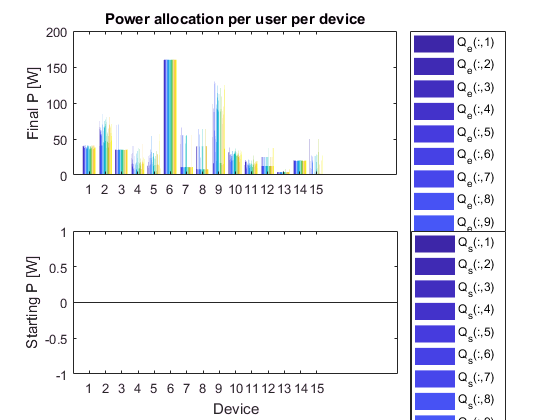

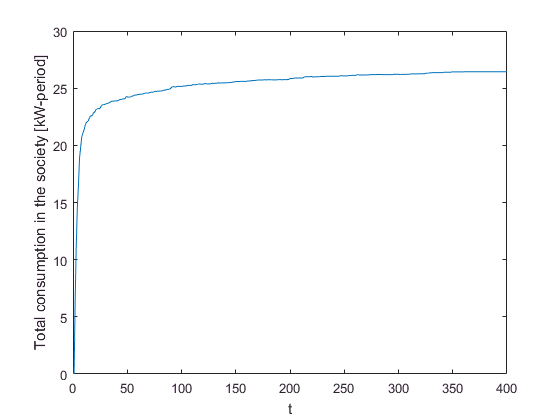

figure(4); 
clf



subplot(2,1,1), bar(Q_e,'DisplayName','Q_e')
titPower = strcat('Final P [W]');%, % addcost: ', num2str(addcost));
%title(titPower)
%xlabel('Device') % x-axis label
ylabel(titPower) % y-axis label
legend('show', 'Location','northeastoutside')

title('Power allocation per user per device')
%figure(5); 
%clf
subplot(2,1,2), bar(Q_s,'DisplayName','Q_s')
titPower = strcat('Starting P [W]');%, % addcost: ', num2str(addcost));
%title(titPower)
xlabel('Device') % x-axis label
ylabel(titPower) % y-axis label
legend('show', 'Location','northeastoutside')






%nameP = strcat('power',netType,num2str(P),social_incentives);
%savefig(4, nameP, 'compact');


%disp(['Energy use ratio: ' num2str(total_resources_alloc/sum(m))]);
timeQ = 1:size(G.Q,1);
Qavg = zeros(1,size(G.Q,1));
for i= timeQ
     Qavg(i) = sum(G.Q(i,:))/1000;
end

figure(6)
plot(timeQ,Qavg)
xlabel('t');
ylabel('Total consumption in the society [kW-period]')


%save('ALL')


## More graphics 

% no me acuerdo para qué era esto

% q_i = 0:0.01:3.5;
% f = 1:10;
% sigma = zeros(length(q_i),length(f));
% for k = f
%     sigma(:,k) = q_i./f(k);
% end
% 

